s = SIGNAL;
col18 = s(:,18);
debut = find(col18 == 1);
fin  = debut + 5120;
fenetrefermee = [debut fin];

col19 = s(:,19);
debut2 = find(col19 == 1);
fin2  = debut2 + 5120;
fenetreouvert = [debut2 fin2];

bloc1 = fenetrefermee(1,:)

bloc1 =        35512       40632


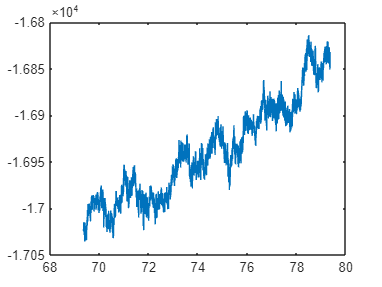

lignes1  = bloc1(1):1:bloc1(2);
valeursbloc1 = s(lignes1,:);
E1 = valeursbloc1(:,[1 2]);
figure, plot(E1(:,1),E1(:,2))

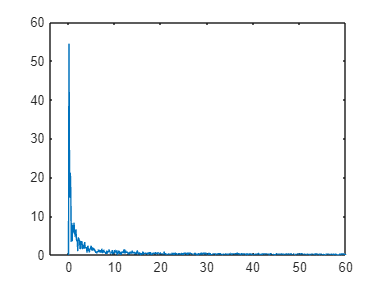


Fs = 512;
N = length(E1(:,2));
fftE1 = abs(fft(E1(:,2) - mean(E1(:,2))) / N);
fftE1 = fftE1(1:floor(N/2)+1);
fftE1(2:end-1) = 2 * fftE1(2:end-1);
f = Fs * (0:floor(N/2)) / N;


figure, plot(f, fftE1);
xlim([-4 60]);